## **Skin-Stringer Panel Design**

 AERO60002 Aerospace Vehicle Design 2024-2025

**Project G1**

% Housekeeping
clear
clc
close all

### **0 Design Parameters**

**0.1 Sea Level**

[T0, a0, P0, rho0] = atmosisa(0);  % Sea level condition
g = 9.80665;                       % Standard acceleration of gravity (m/s^2)

**0.2 Fuselage Properties**

D = 6.38;                          % Fuselage diameter (m)
r = D / 2;                         % Fuselage radius (m)
C = 2 * pi * r;                    % Circumference (m)

**0.3 Material Properties**

Skin (2024 T861)

sigma_skin = 455;                  % Tensile yield stress (MPa)
tau_skin = sigma_skin ./ sqrt(3);  % Shear yield stress (MPa)
rho_skin = 2780;                   % Density (kg/m^3)

Stringer (7068 T6511)

sigma_st = 683;                    % Tensile yield stress (MPa)
tau_st = sigma_st ./ sqrt(3);      % Shear yield stress (MPa)
rho_st = 2850;                     % Density (kg/m^3)

**0.4 Critical Loading Conditions**

Q = 5.951582721709430e+05;         % Maximum shear force (N)
P = 0;                             % Maximum tangential load (N)
M = -5.067912648168767e+06;        % Maximum bending moment (Nm)
T = 1.263599895277778e+06;         % Maximum torque (Nm)

### **1 Optimisation Problem using fmincon with Global research**

compare [fmincon](https://www.mathworks.com/help/optim/ug/fmincon.html) with [GlobalSearch](https://ww2.mathworks.cn/help/gads/globalsearch.html) and [ga](https://ww2.mathworks.cn/help/gads/ga.html), using the best result

**1.0 Initial conditions**

Define the objective function for optimisation problem

fun = @(x) mass(x(1), x(2), x(3), x(4), x(5));             % (t_skin, s_st, t_st, L_st, h_st)

Define initial point for the objective function

x0 = [1 / 1000, 0.23, 2 / 1000, 15 / 1000, 30 / 1000];     % take average from literiture review

Boundary conditions

lb = [1 / 1000, 0.05, 1 / 1000, 1 / 1000, 1 / 1000];       % change dynamically
ub = [20 / 1000, 0.50, 20 / 1000, 100 / 1000, 200 / 1000]; % change dynamically

Nonlinear constraints

nonlcon = @Non_linear;

**1.1 Define problem**

Create optimization problem [createOptimProblem](https://ww2.mathworks.cn/help/gads/createoptimproblem.html)

problem = createOptimProblem('fmincon', 'objective', fun, 'x0', x0, 'lb', lb, 'ub', ub, 'nonlcon', nonlcon, 'options', optimoptions('fmincon', 'Display', 'iter'));

[GlobalSearch](https://ww2.mathworks.cn/help/gads/globalsearch.html)

gs = GlobalSearch;

**1.2 Run optimisation**

[x_opt, f_opt] = run(gs, problem);

### **A Functions**

**A.1 Calculate skin-stringer panel mass per unit length**

% t_skin = 1 / 1000; % Skin thickness (m)

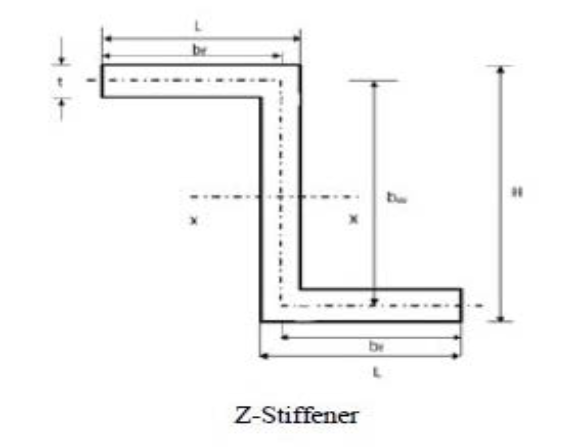

See the 'Fuselage Design' Excel sheet

% s_st = ;           % Stringer spacing (m)
% t_st = ;           % Stringer thickness (m)
% L_st = ;           % Stringer flange (m)
% h_st = ;           % Stringer height (m)

*The optimisation goal is to minimise the total mass, the price of the material is not considered for simplicity of the preliminary design.*

*In addition, lower weight would reduce costs in terms of fuel and give aircraft more design redundencoes.*

% function m_l = mass(t_skin, s_st, t_st, L_st, h_st)

**A.2 Non-linear constriant**

See the Structure 3 Lecture Notes about Interactive buckling in plates